# `Ex002 - Testing all data algorithms`

`data_crop1D()`

close all; clear all;
help data_crop1D

  [xdat_crop, ydat_crop] = data_crop1D(xdat, ydat, xdat_lims, plot_result)
    This function crops 1D data along the x-axis (domain) and y-axis
    (range). The user defines the limits along the x-axis. 
 
    REQ. FUNCTIONS: (none)
 
    IN:
    -   xdat:           [nX×1] array of the x-axis
    -   ydat:           [nY×1] array of the y-axis
  	-   xdat_lims:      [1×2] row vector of x-axis limits
    -   plot_result:    if 1, will plot figure summary, otherwise it wont.
 
    OUT:
    -   xdat_crop:  	[mX×1] array of the cropped x-axis
    -   ydat_crop:   	[mY×1] array of the cropped y-axis



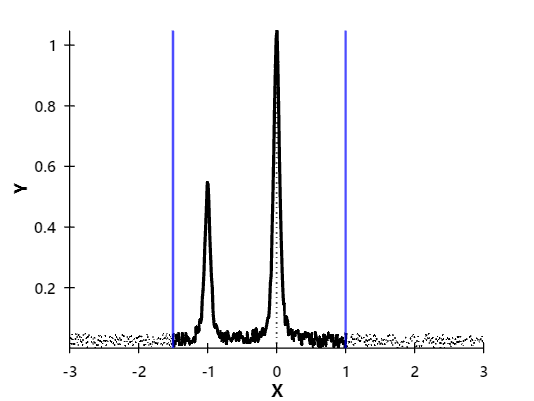

xdat = linspace(-3, 3, 5e2);
ydat    = PESCurve(xdat, "sGLA", 0, 1, 0.1, 0.5, -1.0, 0.5, 0, 0);
ydat    = ydat + 0.05*rand(size(ydat));
xdat_lims = [-1.5,1];
[xdat_crop, ydat_crop] = data_crop1D(xdat, ydat, xdat_lims, 1);

`data_crop2D()`

close all; clear all;
help data_crop2D

  [xdat_crop, ydat_crop, ddat_crop] = data_crop2D(xdat, ydat, ddat, xdat_lims, ydat_lims, plot_result)
    This function crops 2D data along the x- and y-axis. The user can
    define the limits along the x- and y-axis to be cropped.
 
    REQ. FUNCTIONS: (none)
 
    IN:
    -   xdat:           [1×nX] or [nY×nX] array of the x-axis data
    -   ydat:           [nY×1] or [nY×nX] array of the y-axis data
    -   ddat:           [nY×nX] array of the intensity data
  	-   xdat_lims:      [1×2] row vector of x-axis limits
  	-   ydat_lims:      [1×2] row vector of y-axis limits
    -   plot_result:    if 1, will plot figure summary, otherwise it wont.
 
    OUT:
    -   xdat_crop:  	[mY×mX] array of the cropped x-axis
    -   ydat_crop:   	[mY×mX] array of the cropped y-axis
    -   ddat_crop:  	[mY×mX] array of the cropped intensity data



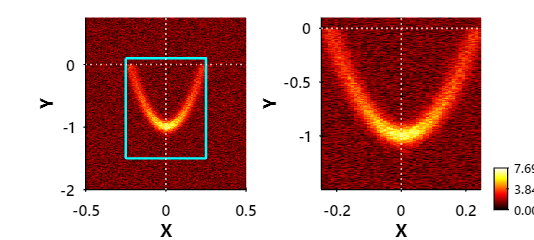

xdat = linspace(-0.5, 0.5, 1e2);
ydat = linspace(-2, 0.75, 1e3)';
ddat    = ARPESCurve_FDD(xdat, ydat, "G2DA", 1, 0, -1, 0.05, 0.15, 0.20, 0.00, 12);
ddat    = ddat + 0.50*rand(size(ddat))*max(ddat(:));
xdat_lims = [-0.25, 0.25];
ydat_lims = [-1.5,0.10];
[xdat_crop, ydat_crop, ddat_crop] = data_crop2D(xdat, ydat, ddat, xdat_lims, ydat_lims, 1);

`data_filter1D()`

close all; clear all;
help data_filter1D

  ydat_fil = data_filter1D(ydat, filType, filArgs, plot_result)
    This function applies a filtering / smoothing operation on 1D data.
 
    IN:
    -   ydat:           [nY×1] column vector of the output range.
    -   filType:    	string of the type of filtering to use. Default: "savitzky-golay" ("none","gaco1","savitzky-golay","movmean","movmedian","gaussian").
    -   filArgs:       	cell-array of the filtering / smoothing arguments:
                             -> gaco1:          1x1     {half-width of Gaussian}
                             -> savitzky-golay: 2x1     {Order, Window Size}
                             -> movmean:        1x1     {Window Size}
                             -> movmedian:      1x1     {Window Size}
                             -> gaussian:       1x1     {half-width of Gaussian}
    -   plot_result:    if 1, will plot figure summary, otherwise it wont.
 
    OUT:
    -   ydat_fil:       [nY×1] column vector of the filtered data.



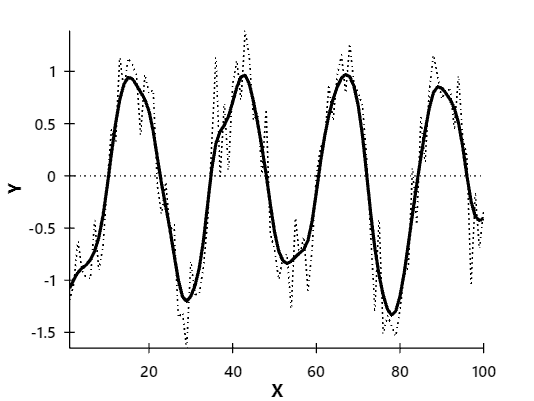

xdat = 100*linspace(0,1,1e2);
ydat = cos(2*pi*0.04*xdat+2*pi*rand) + 0.35*randn(1,100);
% 1 - Filtering the data
filType{1} = "g1";         ydat_fil{1} = data_filter1D(ydat, 'g1', {2}, 1);

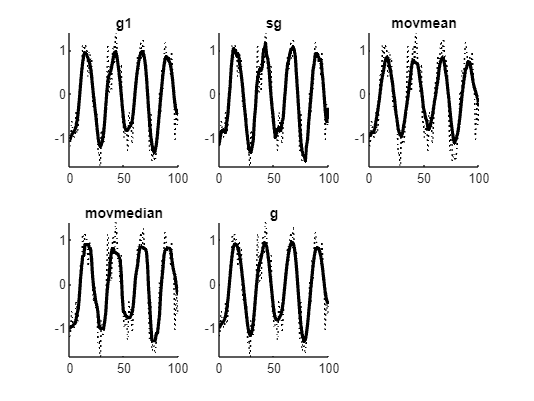

filType{2} = "sg";         ydat_fil{2} = data_filter1D(ydat, 'sg', {3, 9}, 0);
filType{3} = "movmean";    ydat_fil{3} = data_filter1D(ydat, "movmean", {10}, 0);
filType{4} = "movmedian";  ydat_fil{4} = data_filter1D(ydat, "movmedian", {10}, 0);
filType{5} = "g";          ydat_fil{5} = data_filter1D(ydat, "g", {10}, 0);
% 2 - Plotting the results
figure(); hold on;
for i = 1:length(ydat_fil)
    subplot(2,3,i); hold on;
    plot(xdat, ydat, 'k:', 'linewidth', 1);
    plot(xdat, ydat_fil{i}, 'k-', 'linewidth', 2);
    title(filType{i});
    axis([min(xdat(:)), max(xdat(:)), min(ydat(:)), max(ydat(:))]);
end

`data_filter2D()`

close all; clear all;
help data_filter2D

  zdat_fil = data_filter2D(zdat, filType, filArgs, plot_result)
    This function applies a filtering / smoothing operation on 2D data.
 
    REQ. FUNCTIONS:
    -   AA = Gaco2(A,hwX,hwY [,hsX] [,hsY])
    -   AA = GaussFlt2(Img,hwX,hwY,hsX,hsY)
    -   AA = LaplaceFlt2(Img [,y2xRatio] [,order])
    -   AA = CurvatureFlt2(Img [,order] [,CX] [,CY]) 
 
    IN:
    -   zdat:           [nX×nY] array of the intensity data. Smoothes along the [N×M] axis.
    -   filType:        string of the type of filtering to use. Default: "spline" ("none","Gaco2","GaussFlt2","LaplaceFlt2","CurvatureFlt2").
    -   filArgs:       	cell-array of the filtering / smoothing arguments:
                             -> gaco2:          2x1     {hwX, hwY}              : {1, 1}
                             -> gaussflt2:      4x1     {hwX, hwY, hsX, hsY}    : {1, 1, 3, 3}
                             -> laplaceflt2:    2x1     {y2xRatio, order}       : {1, '4th'}
                             -> curv

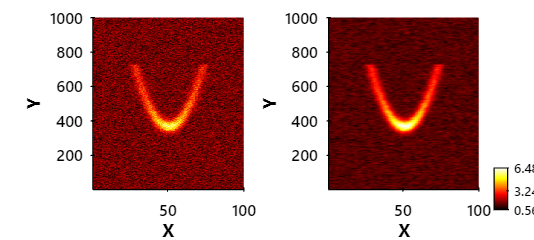

xdat = linspace(-0.5, 0.5, 1e2);
ydat = linspace(-2, 0.75, 1e3)';
ddat    = ARPESCurve_FDD(xdat, ydat, "G2DA", 1, 0, -1, 0.05, 0.15, 0.20, 0.00, 12);
ddat    = ddat + 0.50*rand(size(ddat))*max(ddat(:));
% 1 - Filtering the data
ddat_fil{1} = data_filter2D(ddat, 'gaco2', {1,2}, 1);

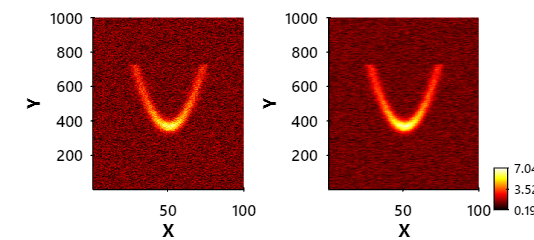

ddat_fil{2} = data_filter2D(ddat, 'gaussflt2', {1,1,3,3}, 1);

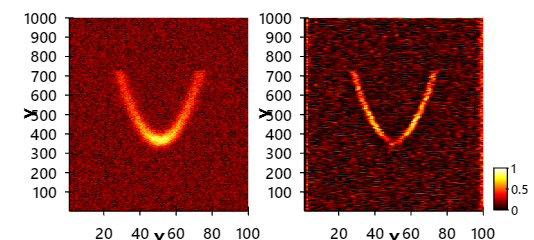

ddat_fil{3} = data_filter2D(ddat, "laplaceflt2", {1, '4th'}, 1);

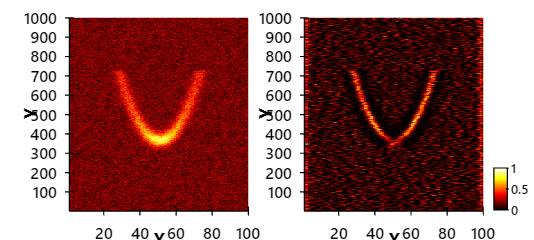

ddat_fil{4} = data_filter2D(ddat, "curvatureflt2", {'2D',2, 2}, 1);

`find_peak_loc() & find_peak_fwhm()`

close all; clear all;
help find_peak_loc

  [xVal, yVal] = find_peak_loc(xdat, ydat, xWin, type, plot_results)
    This function is used to determine both the maximum value and position of
    a data set using a range of different methods; spline interpolation or
    curve fitting a gaussian / voigt function. 
 
    IN:
    -   xdat:           [N×1] column vector of the input domain.
    -   ydat:           [N×1] column vector of the output range.
    -   xWin:           [N×2] array that contains the x-windows where N peaks are expected to be found.
    -   type:           string of the type of method to use. Default: "spline" ("none","spline","gaco1","G","L","sGL","pGL","sGLA","pGLA").
    -   plot_result:    if 1, will plot figure summary, otherwise it wont.
 
    OUT:
    -   xVal:           scalar or [N×1] column vector of the maxima x-values.
    -   yVal:           scalar or [N×1] column vector of the maxima y-values.



help find_peak_fwhm

  [fwhm, fwhmLocs] = find_peak_fwhm(xdat, ydat, xWin, type, plot_result)
    This function is used to determine both the fwhm of a data set using 
    a range of different methods; spline interpolation or curve fitting a 
    gaussian / voigt function. 
 
    REQ. FUNCTIONS: (none)
 
    IN:
    -   xdat:           [N×1] column vector of the input domain.
    -   ydat:           [N×1] column vector of the output range.
    -   xWin:           [N×2] array that contains the x-windows where N peaks are expected to be found.
    -   type:           string of the type of method to use. Default: "spline" ("none","spline","gaco1","G","L","sGL","pGL","sGLA","pGLA").
    -   plot_result:    if 1, will plot figure summary, otherwise it wont.
 
    OUT:
    -   fwhm:           scalar or [N×1] column vector of the fwhm of each peak defined.
    -   fwhmLocs:   	[2N×2] column vector of the fwhm positions.



ans = 10

1) x = 49.50, y = 5.83 


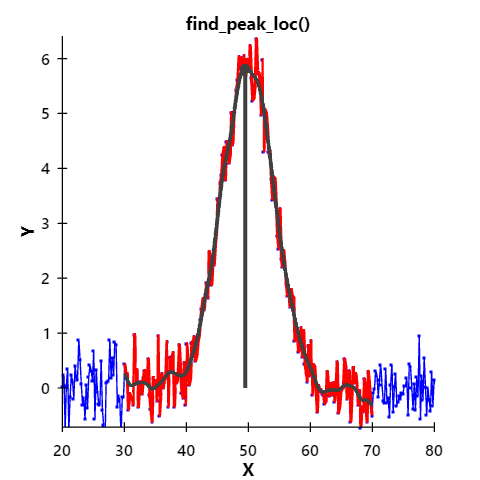

xdat = 100*linspace(0,1,5e2);
ydat = Gauss(xdat, 50, 6.0, 10)' + 0.35*randn(1,length(xdat));
[xval, yval] = find_peak_loc(xdat, ydat, [30, 70], "gaco1", 1);

1) x = 49.50, y = 5.83, fwhm = 10.08 


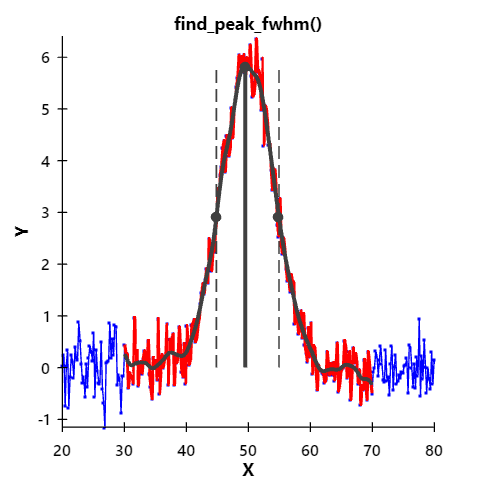

[xval, yval] = find_peak_fwhm(xdat, ydat, [30, 70], "gaco1", 1);

`Linear Transformations`

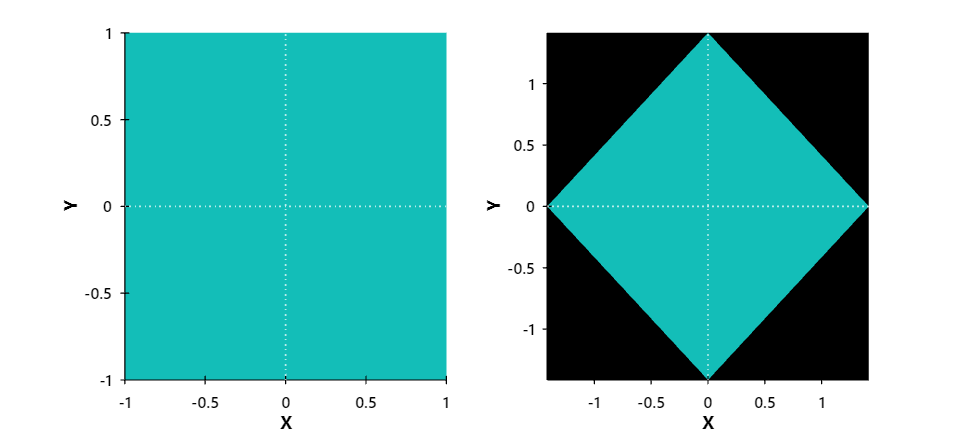

close all; clear all;
[xdat, ydat] = meshgrid(-1:1,-1:1);
lt_rotate(xdat, ydat, {45}, 1);

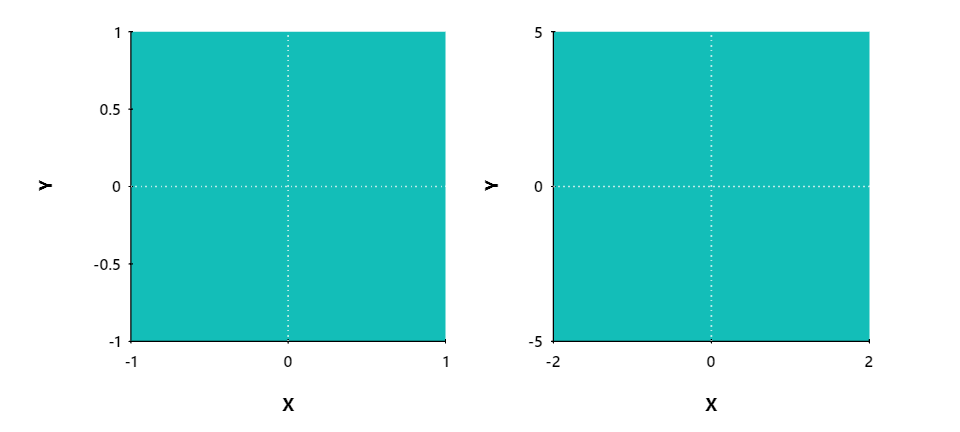

lt_scale(xdat, ydat, {2,5}, 1);

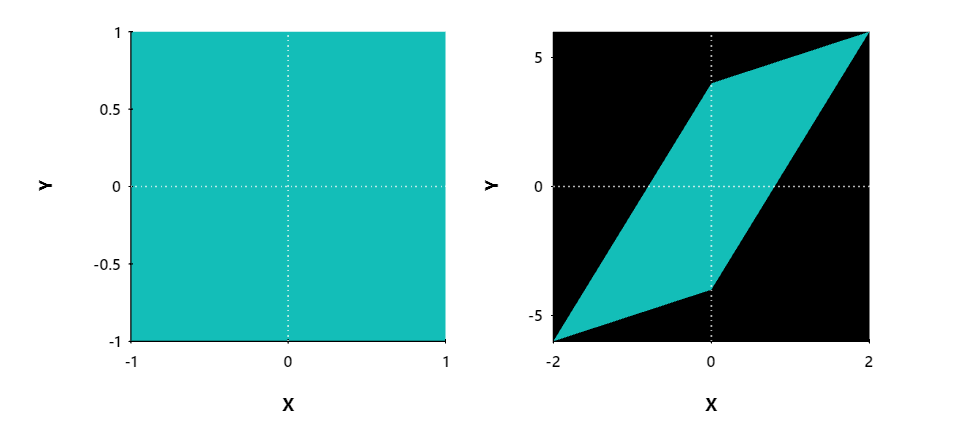

lt_shear(xdat, ydat, {1, 0.2}, 1);

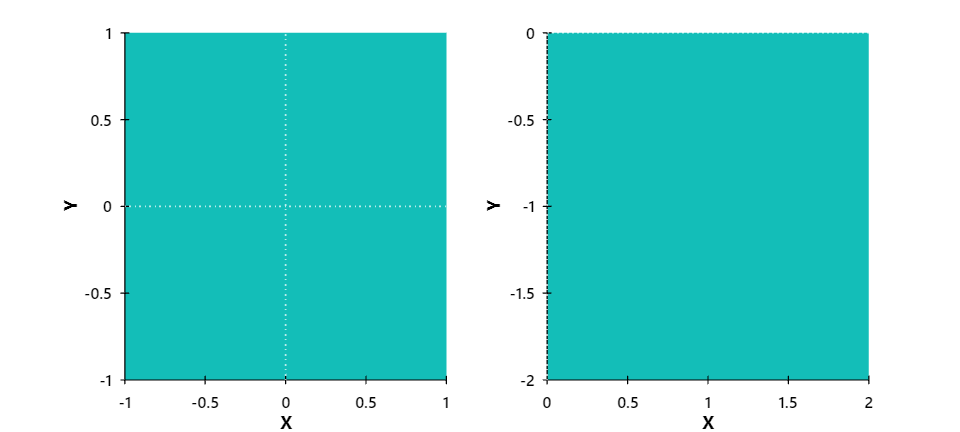

lt_translate(xdat, ydat, {1, -1}, 1);